# Timing Variation Simulation

## [1] Simulator Initialization

Initialize the simulator by setting default parameters for the attacker and victim

simulator = Simulator();
%setup the victim's chirp parameters

simulator.load_realistic_victim_params;
simulator.load_realisitc_attacker_params;

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.timing_offset_us = (range2time(75,physconst('LightSpeed')))* 1e6/2; %propogating 1 way, distance defaults to 7m 

%configure the FMCW parameters
simulator.configure_FMCW_parameters();

%load default target, attacker, and victim positions and velocities
simulator.load_target_realistic;
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 10.76 MHz/us
	 Idle Time: 			 7.88 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.42 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 7.17 MSps
	 Ramp End Time: 		 42.12 us
	 Chirp Tx Bandwidth: 		 453.21 MHz
	 Chirp Sampling Bandwidth: 	 384.18 MHz
	 ADC Sampling Period: 		 35.70 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 3.89 mm


simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 32
	 FramePeriodicity 		 33.33 ms
	 Active Frame Time 		 1.60 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 99.88 m
	 Range Resolution 		 0.39 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 1.22 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 458.88 MHz
	 Downsampling factor 		 64
	 Sweep time 			 42.12 us


simulator.Attacker.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 10.76 MHz/us
	 Idle Time: 			 7.88 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.42 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 7.17 MSps
	 Ramp End Time: 		 42.12 us
	 Chirp Tx Bandwidth: 		 453.21 MHz
	 Chirp Sampling Bandwidth: 	 384.18 MHz
	 ADC Sampling Period: 		 35.70 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 3.89 mm


simulator.Attacker.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 32
	 FramePeriodicity 		 33.50 ms
	 Active Frame Time 		 1.60 ms


simulator.Attacker.print_performance_specs;

Performance Specifications
	 Max Range 			 99.88 m
	 Range Resolution 		 0.39 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 1.22 m/s


simulator.Attacker.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 458.88 MHz
	 Downsampling factor 		 
	 Sweep time 			 42.12 us


## [2] Plot the Victim Chirp

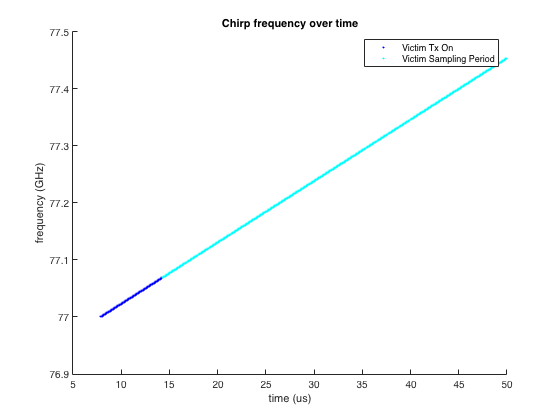

figure;
ax = axes;
victim_chirp = 1;
victim_frame = 1;
simulator.plot_specified_radar_chirp(ax,simulator.Victim,victim_chirp, victim_frame);

## [3] Overlay Attacker Interference (if any)

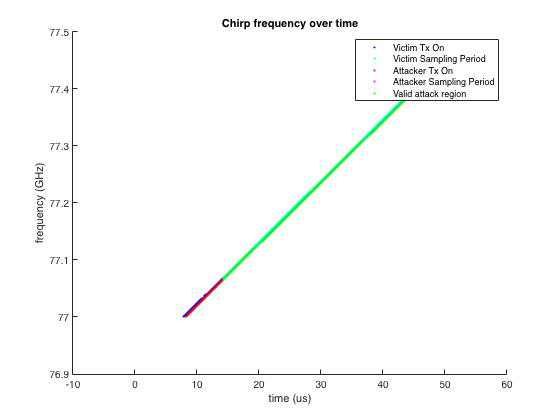

clf;
ax = axes;
simulator.plot_attacker_and_victim_chirps(ax,victim_frame,victim_chirp);

## [4] Plot Victim Frame

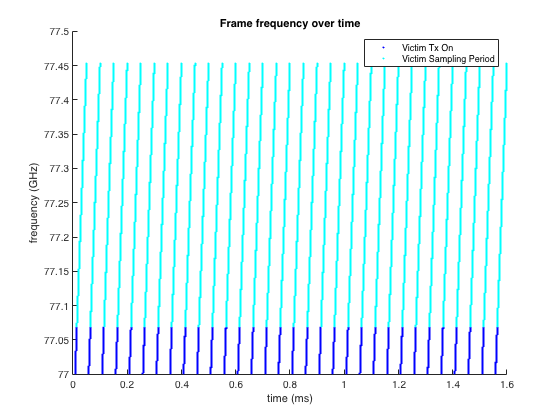

clf;
ax = axes;
simulator.plot_specified_radar_frame(ax,simulator.Victim,victim_frame);

## [5] Overlay Attacker Interference

Here, the green regions identify that the attacker is successfully interfering with the victim

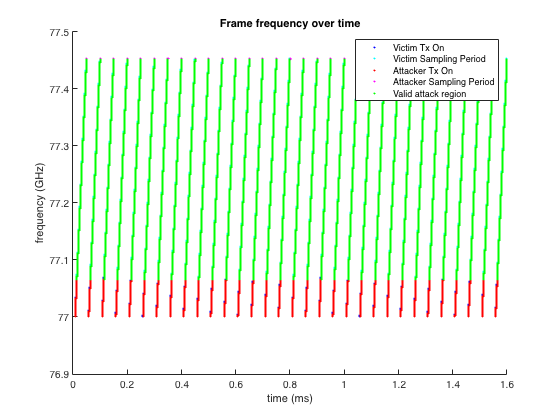

clf;
ax = axes;
simulator.plot_attacker_and_victim_frames(ax,victim_frame)

## [6] Load the Simulink Model

%initialize other variables needed in the simulation
victim_num_adc_samples = simulator.Victim.ADC_Samples;

open_system('FMCWSim');
set_param('FMCWSim','StopTime','32 * simulator.Victim.sweep_time')